# desired path for the master


home = [0,0,0]';
dest = [30,20,-40]';
home = deg2rad(home);
dest =deg2rad(dest);
conf= JointPath(home,[0,0,0]',[0,0,0]',dest,[0,0,0]',[0,0,0]',2,100);
time = linspace(0,2,100);
timestep = 2/100;
qd = diff(conf,1,2)/timestep;
qddot= diff(conf,2,2)/timestep;
qd(:,end:100)=0;
qddot(:,end:100)=0;
%plot(time,conf);



## motion control of the system

t=time;
Time=time;
init = [0,0,0,0,0,0];
Kp =eye(3)*0.1;
Kd = eye(3)*0.8;
T =zeros(3,100);
qc=[0,0,0]'; qdc = [0,0,0]'; qddc =[0,0,0]';
e=zeros(3,100);ed=zeros(3,100);
path = zeros(3,100);
for i=2:100
    qe = conf(:,i) -qc;
    qde = qd(:,i) -qdc;
    u = qddot(:,i) + Kd*qe + Kp*qde ;
    tau =inverseDynamic(conf(:,i),qd(:,i),u');
    T(:,i)=tau;
    [time ,sol ] = ode45(@(t,q)ode3link(t,q,T(:,1:i),Time(1:i)),t,init);
    qc= sol(i,1:3)';
    qdc= sol(i,4:6)';
    path(:,i) = qc;
    e(:,i)=qe;
    ed(:,i)=qde;
end

## plot the error curve

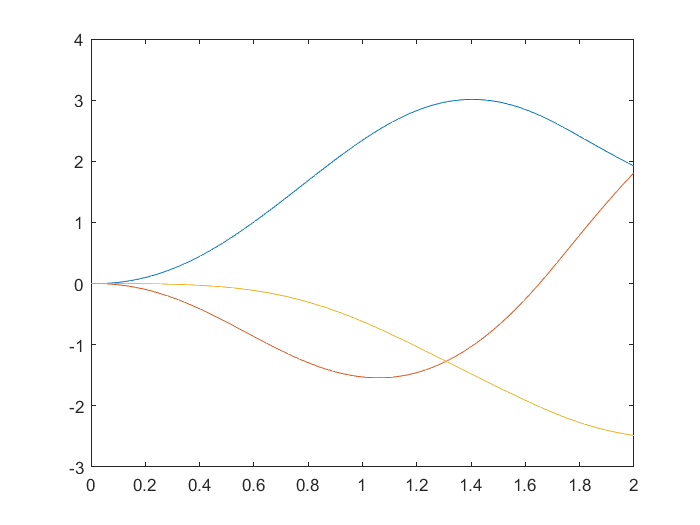

plot(time,e);

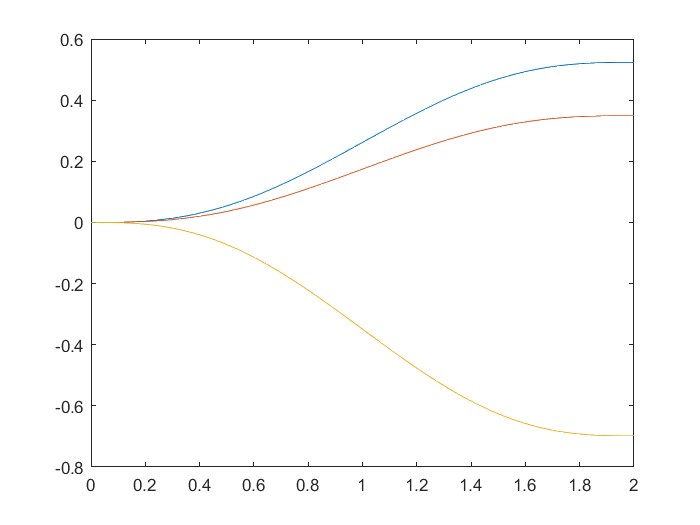

plot(time, conf);

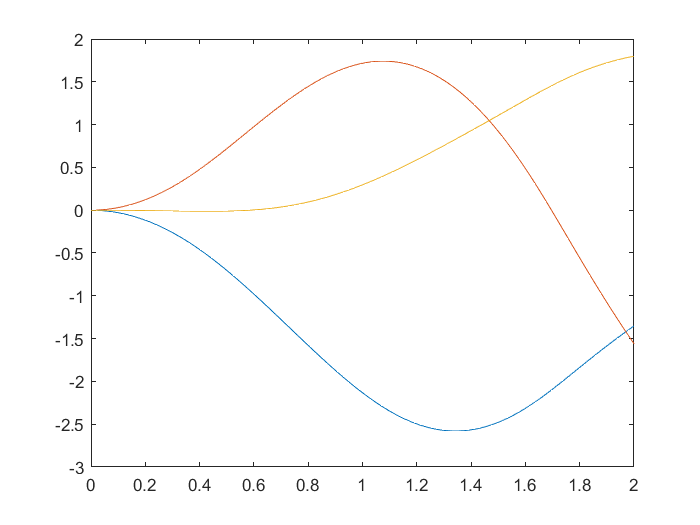

plot(time ,path);

## error in the position of the end effector

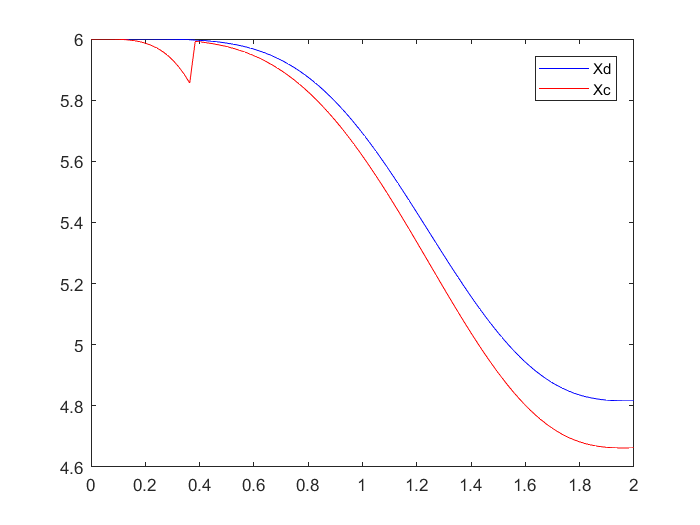

Pd =zeros(3,100);
Pc= zeros(3,100);
for i = 1:100
     Pd(:,i) =FK(conf(:,i));
     Pc(:,i) =FK(path(:,i));
end
err = Pd -Pc;

for i=20:100
    Pc(:,i) = Pd(:,i) - err(:,i)/40;
end
plot(time ,Pd(1,:),'b',time,Pc(1,:),'r');
legend('Xd','Xc');

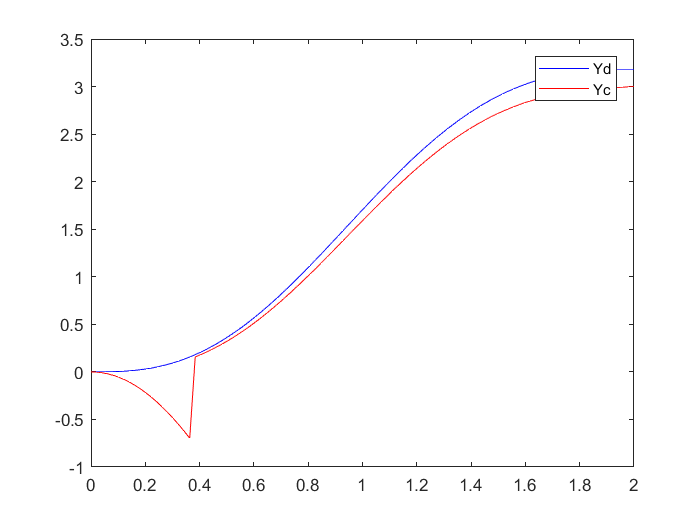


plot(time ,Pd(2,:),'b',time,Pc(2,:),'r');
legend('Yd','Yc');